## **Proyecto Retropropagación**

### **1. Cargar dataset iris.csv**

dataset = readtable('iris.csv');



X = dataset{:, 1:end-1};
y = dataset{:, end};

num_samples = size(X, 1);
shuffled_indices = randperm(num_samples);
X = X(shuffled_indices, :);
y = y(shuffled_indices, :);

disp(head(dataset, 5));

    sepal_length    sepal_width    petal_length    petal_width     variety  
    ____________    ___________    ____________    ___________    __________

        5.1             3.5            1.4             0.2        {'Setosa'}
        4.9               3            1.4             0.2        {'Setosa'}
        4.7             3.2            1.3             0.2        {'Setosa'}
        4.6             3.1            1.5             0.2        {'Setosa'}
          5             3.6            1.4             0.2        {'Setosa'}



- División de entrenamiento y test.

porcentaje_entrenamiento = 0.8;

num_entrenamiento = round(porcentaje_entrenamiento * num_samples);
num_prueba = num_samples - num_entrenamiento;

X_entrenamiento = X(1:num_entrenamiento, :);
y_entrenamiento = y(1:num_entrenamiento, :);

X_prueba = X(num_entrenamiento + 1:end, :);
y_prueba = y(num_entrenamiento + 1:end, :);

### 2. Inicializar la red neuronal con valores aleatorios.

- Garantizar que los resultados sean los mismos con la semilla.

semilla = 42;
rng(semilla);
red = inicializar_red(size(X, 2), numel(unique(y)), [8,10]);
for i = 1:length(red)
    capa = red{i};
    neuron = size(capa, 2);
    entradas = size(capa, 1) - 1;
    disp(['Capa ', num2str(i), ' tiene ', num2str(entradas), ' entradas y un total de ', num2str(neuron), ' neuronas']);
end

Capa 1 tiene 3 entradas y un total de 8 neuronas
Capa 2 tiene 7 entradas y un total de 10 neuronas
Capa 3 tiene 9 entradas y un total de 3 neuronas


### 3. Codificar las categorías de la clase con one-hot-encoder.

y_entrenamiento = one_hot_encoder(y_entrenamiento);
y_prueba = one_hot_encoder(y_prueba);

### 4. Entrenamiento de pesos.

epochs = 100;
batch_size = 20;

[red_entrenada, cross_entropy_historico, accuracy] = train(red, X_entrenamiento, y_entrenamiento, epochs, batch_size);

Epoch 1/100 - loss: 35.6353 - accuracy: 26.67%
Epoch 2/100 - loss: 28.2277 - accuracy: 26.67%
Epoch 3/100 - loss: 24.7704 - accuracy: 52.50%
Epoch 4/100 - loss: 22.9731 - accuracy: 38.33%
Epoch 5/100 - loss: 22.1248 - accuracy: 38.33%
Epoch 6/100 - loss: 21.7450 - accuracy: 38.33%
Epoch 7/100 - loss: 21.5443 - accuracy: 38.33%
Epoch 8/100 - loss: 21.4003 - accuracy: 38.33%
Epoch 9/100 - loss: 21.2711 - accuracy: 43.33%
Epoch 10/100 - loss: 21.1434 - accuracy: 46.67%
Epoch 11/100 - loss: 21.0122 - accuracy: 48.33%
Epoch 12/100 - loss: 20.8754 - accuracy: 49.17%
Epoch 13/100 - loss: 20.7313 - accuracy: 51.67%
Epoch 14/100 - loss: 20.5785 - accuracy: 52.50%
Epoch 15/100 - loss: 20.4160 - accuracy: 54.17%
Epoch 16/100 - loss: 20.2426 - accuracy: 54.17%
Epoch 17/100 - loss: 20.0575 - accuracy: 54.17%
Epoch 18/100 - loss: 19.8598 - accuracy: 61.67%
Epoch 19/100 - loss: 19.6487 - accuracy: 79.17%
Epoch 20/100 - loss: 19.4237 - accuracy: 80.83%
Epoch 21/100 - loss: 19.1845 - accuracy: 80.83%
E

- Precisión de la red

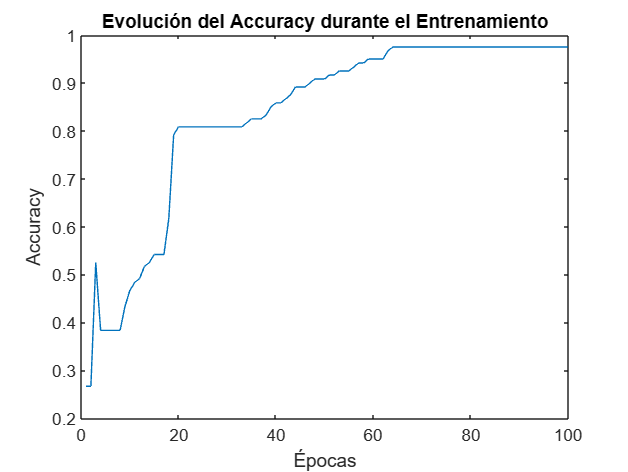

epocas_vec = 1:size(accuracy, 2);

plot(epocas_vec, accuracy);
title('Evolución del Accuracy durante el Entrenamiento');
xlabel('Épocas');
ylabel('Accuracy');

- Pérdida de la red

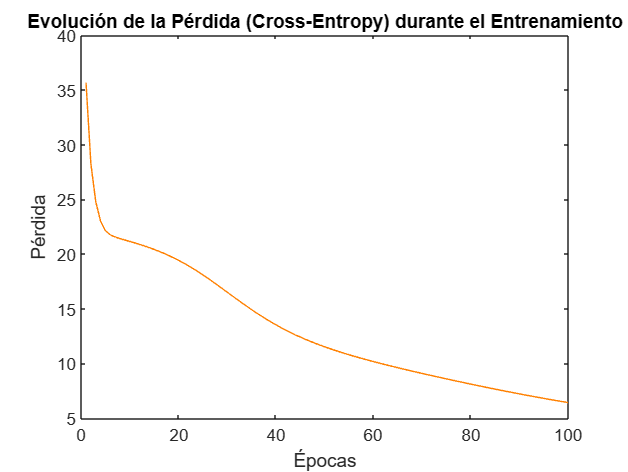

plot(epocas_vec, cross_entropy_historico, 'Color', [1, 0.5, 0]);
title('Evolución de la Pérdida (Cross-Entropy) durante el Entrenamiento');
xlabel('Épocas');
ylabel('Pérdida');

### 5. Probando diversas arquitecturas.

- **Arquitectura sencilla: Red con 3 capas. 2 neuronas capa oculta**

semilla = 42;
rng(semilla);
red = inicializar_red(size(X, 2), numel(unique(y)), [2]);

epochs = 200;
batch_size = 10;

[red_entrenada2, cross_entropy_historico, accuracy] = train(red, X_entrenamiento, y_entrenamiento, epochs, batch_size);

Epoch 1/200 - loss: 12.5214 - accuracy: 38.33%
Epoch 2/200 - loss: 11.9980 - accuracy: 38.33%
Epoch 3/200 - loss: 11.4806 - accuracy: 38.33%
Epoch 4/200 - loss: 11.1402 - accuracy: 38.33%
Epoch 5/200 - loss: 11.0402 - accuracy: 38.33%
Epoch 6/200 - loss: 11.0093 - accuracy: 38.33%
Epoch 7/200 - loss: 10.9934 - accuracy: 38.33%
Epoch 8/200 - loss: 10.9814 - accuracy: 38.33%
Epoch 9/200 - loss: 10.9700 - accuracy: 38.33%
Epoch 10/200 - loss: 10.9572 - accuracy: 38.33%
Epoch 11/200 - loss: 10.9420 - accuracy: 38.33%
Epoch 12/200 - loss: 10.9230 - accuracy: 38.33%
Epoch 13/200 - loss: 10.8993 - accuracy: 38.33%
Epoch 14/200 - loss: 10.8697 - accuracy: 38.33%
Epoch 15/200 - loss: 10.8337 - accuracy: 38.33%
Epoch 16/200 - loss: 10.7909 - accuracy: 38.33%
Epoch 17/200 - loss: 10.7414 - accuracy: 38.33%
Epoch 18/200 - loss: 10.6853 - accuracy: 38.33%
Epoch 19/200 - loss: 10.6231 - accuracy: 38.33%
Epoch 20/200 - loss: 10.5553 - accuracy: 38.33%
Epoch 21/200 - loss: 10.4825 - accuracy: 38.33%
E

- Precisión de la red

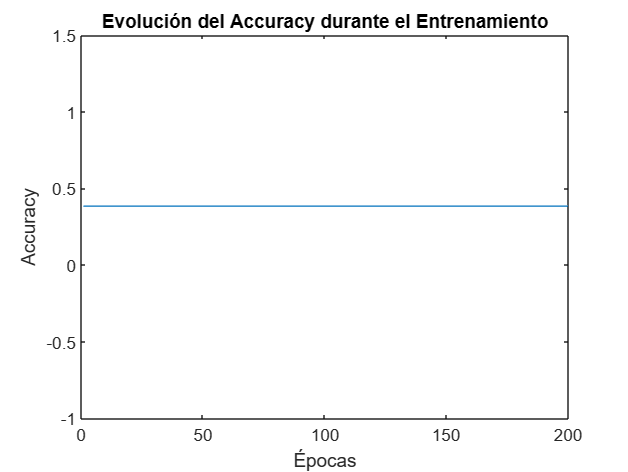

epocas_vec = 1:size(accuracy, 2);

plot(epocas_vec, accuracy);
title('Evolución del Accuracy durante el Entrenamiento');
xlabel('Épocas');
ylabel('Accuracy');

- Pérdida de la red

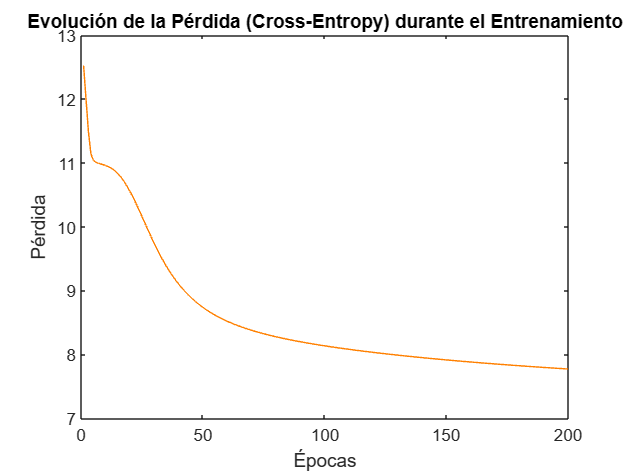

plot(epocas_vec, cross_entropy_historico, 'Color', [1, 0.5, 0]);
title('Evolución de la Pérdida (Cross-Entropy) durante el Entrenamiento');
xlabel('Épocas');
ylabel('Pérdida');

- **Arquitectura básica: Red con 3 capas. **

semilla = 42;
rng(semilla);
red = inicializar_red(size(X, 2), numel(unique(y)), [4]);

epochs = 50;
batch_size = 10;

[red_entrenada3, cross_entropy_historico, accuracy] = train(red, X_entrenamiento, y_entrenamiento, epochs, batch_size);

Epoch 1/50 - loss: 10.8655 - accuracy: 35.00%
Epoch 2/50 - loss: 10.6531 - accuracy: 35.00%
Epoch 3/50 - loss: 10.4683 - accuracy: 35.00%
Epoch 4/50 - loss: 10.2978 - accuracy: 44.17%
Epoch 5/50 - loss: 10.1342 - accuracy: 60.83%
Epoch 6/50 - loss: 9.9733 - accuracy: 60.83%
Epoch 7/50 - loss: 9.8125 - accuracy: 62.50%
Epoch 8/50 - loss: 9.6507 - accuracy: 68.33%
Epoch 9/50 - loss: 9.4871 - accuracy: 66.67%
Epoch 10/50 - loss: 9.3219 - accuracy: 65.00%
Epoch 11/50 - loss: 9.1551 - accuracy: 65.00%
Epoch 12/50 - loss: 8.9874 - accuracy: 65.00%
Epoch 13/50 - loss: 8.8193 - accuracy: 65.00%
Epoch 14/50 - loss: 8.6516 - accuracy: 65.00%
Epoch 15/50 - loss: 8.4849 - accuracy: 65.00%
Epoch 16/50 - loss: 8.3200 - accuracy: 65.00%
Epoch 17/50 - loss: 8.1576 - accuracy: 65.00%
Epoch 18/50 - loss: 7.9985 - accuracy: 65.00%
Epoch 19/50 - loss: 7.8433 - accuracy: 65.00%
Epoch 20/50 - loss: 7.6928 - accuracy: 65.00%
Epoch 21/50 - loss: 7.5474 - accuracy: 65.00%
Epoch 22/50 - loss: 7.4077 - accuracy:

- Precisión de la red

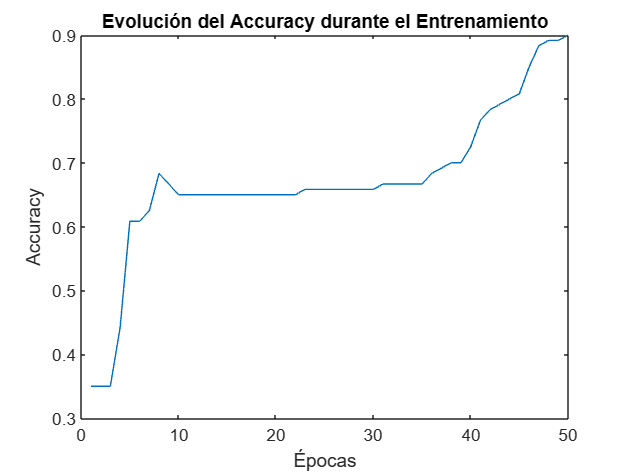

epocas_vec = 1:size(accuracy, 2);

plot(epocas_vec, accuracy);
title('Evolución del Accuracy durante el Entrenamiento');
xlabel('Épocas');
ylabel('Accuracy');

- Pérdida de la red

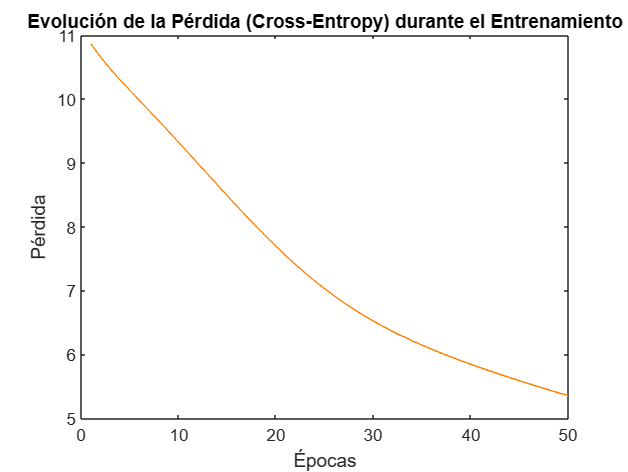

plot(epocas_vec, cross_entropy_historico, 'Color', [1, 0.5, 0]);
title('Evolución de la Pérdida (Cross-Entropy) durante el Entrenamiento');
xlabel('Épocas');
ylabel('Pérdida');

- **Red con Capas Ocultas Más Profundas: Red con 2 capas ocultas: 6 y 8 neuronas.**

semilla = 42;
rng(semilla);
red = inicializar_red(size(X, 2), numel(unique(y)), [6,8]);

epochs = 200;
batch_size = 20;

[red_entrenada4, cross_entropy_historico, accuracy] = train(red, X_entrenamiento, y_entrenamiento, epochs, batch_size);

Epoch 1/200 - loss: 21.2602 - accuracy: 38.33%
Epoch 2/200 - loss: 20.6771 - accuracy: 38.33%
Epoch 3/200 - loss: 20.3259 - accuracy: 38.33%
Epoch 4/200 - loss: 20.0729 - accuracy: 41.67%
Epoch 5/200 - loss: 19.8565 - accuracy: 63.33%
Epoch 6/200 - loss: 19.6493 - accuracy: 64.17%
Epoch 7/200 - loss: 19.4390 - accuracy: 65.00%
Epoch 8/200 - loss: 19.2212 - accuracy: 65.00%
Epoch 9/200 - loss: 18.9943 - accuracy: 65.00%
Epoch 10/200 - loss: 18.7588 - accuracy: 65.00%
Epoch 11/200 - loss: 18.5158 - accuracy: 65.00%
Epoch 12/200 - loss: 18.2665 - accuracy: 65.00%
Epoch 13/200 - loss: 18.0124 - accuracy: 65.00%
Epoch 14/200 - loss: 17.7551 - accuracy: 65.00%
Epoch 15/200 - loss: 17.4959 - accuracy: 65.00%
Epoch 16/200 - loss: 17.2361 - accuracy: 65.00%
Epoch 17/200 - loss: 16.9770 - accuracy: 65.00%
Epoch 18/200 - loss: 16.7197 - accuracy: 65.00%
Epoch 19/200 - loss: 16.4653 - accuracy: 65.00%
Epoch 20/200 - loss: 16.2148 - accuracy: 65.83%
Epoch 21/200 - loss: 15.9689 - accuracy: 65.83%
E

- Precisión de la red

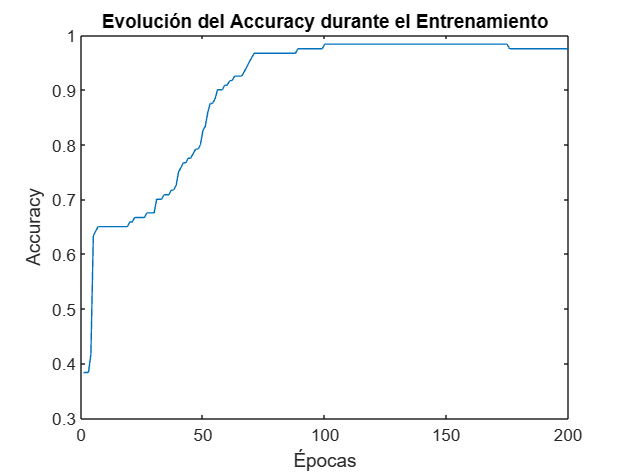

epocas_vec = 1:size(accuracy, 2);

plot(epocas_vec, accuracy);
title('Evolución del Accuracy durante el Entrenamiento');
xlabel('Épocas');
ylabel('Accuracy');

- Pérdida de la red

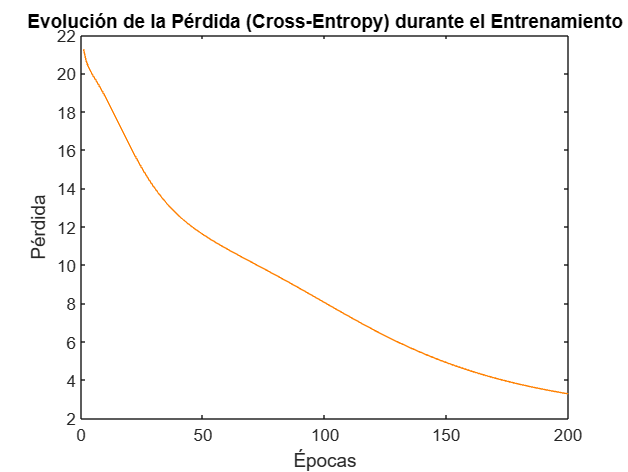

plot(epocas_vec, cross_entropy_historico, 'Color', [1, 0.5, 0]);
title('Evolución de la Pérdida (Cross-Entropy) durante el Entrenamiento');
xlabel('Épocas');
ylabel('Pérdida');

- **Red compleja de 5 capas profundas.**

semilla = 42;
rng(semilla);
red = inicializar_red(size(X, 2), numel(unique(y)), [6,8,10,12,15]);

epochs = 450;
batch_size = 10;

[red_entrenada5, cross_entropy_historico, accuracy] = train(red, X_entrenamiento, y_entrenamiento, epochs, batch_size);

Epoch 1/450 - loss: 13.9095 - accuracy: 35.00%
Epoch 2/450 - loss: 11.1698 - accuracy: 35.00%
Epoch 3/450 - loss: 10.9450 - accuracy: 35.00%
Epoch 4/450 - loss: 10.9228 - accuracy: 35.00%
Epoch 5/450 - loss: 10.9207 - accuracy: 35.83%
Epoch 6/450 - loss: 10.9203 - accuracy: 40.83%
Epoch 7/450 - loss: 10.9198 - accuracy: 41.67%
Epoch 8/450 - loss: 10.9192 - accuracy: 41.67%
Epoch 9/450 - loss: 10.9184 - accuracy: 41.67%
Epoch 10/450 - loss: 10.9177 - accuracy: 41.67%
Epoch 11/450 - loss: 10.9169 - accuracy: 41.67%
Epoch 12/450 - loss: 10.9161 - accuracy: 41.67%
Epoch 13/450 - loss: 10.9153 - accuracy: 41.67%
Epoch 14/450 - loss: 10.9145 - accuracy: 40.83%
Epoch 15/450 - loss: 10.9136 - accuracy: 40.83%
Epoch 16/450 - loss: 10.9128 - accuracy: 40.83%
Epoch 17/450 - loss: 10.9119 - accuracy: 40.83%
Epoch 18/450 - loss: 10.9110 - accuracy: 40.83%
Epoch 19/450 - loss: 10.9101 - accuracy: 40.83%
Epoch 20/450 - loss: 10.9092 - accuracy: 40.83%
Epoch 21/450 - loss: 10.9083 - accuracy: 41.67%
E

- Precisión de la red

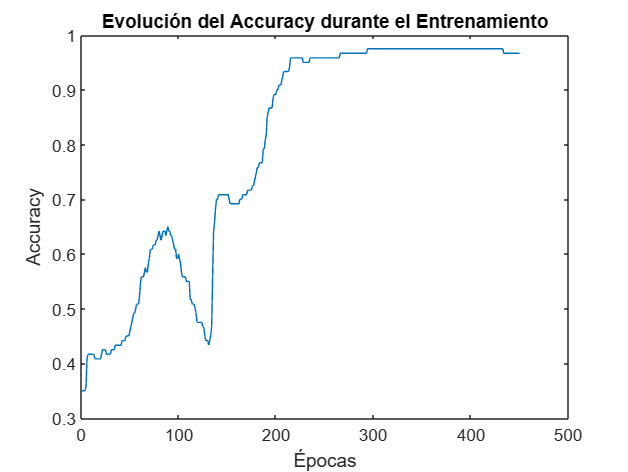

epocas_vec = 1:size(accuracy, 2);

plot(epocas_vec, accuracy);
title('Evolución del Accuracy durante el Entrenamiento');
xlabel('Épocas');
ylabel('Accuracy');

- Pérdida de la red

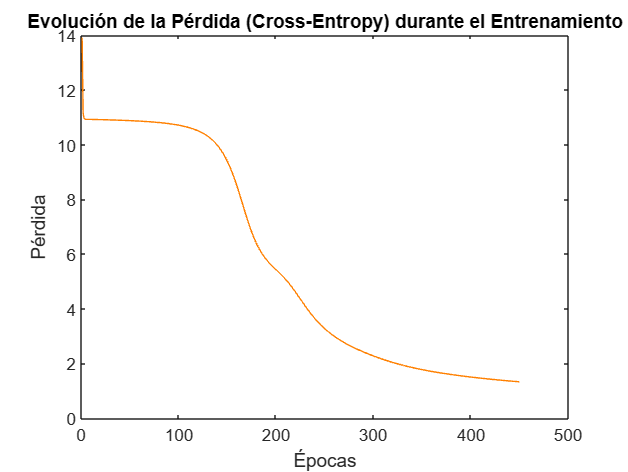

plot(epocas_vec, cross_entropy_historico, 'Color', [1, 0.5, 0]);
title('Evolución de la Pérdida (Cross-Entropy) durante el Entrenamiento');
xlabel('Épocas');
ylabel('Pérdida');

### 6. Realizar predicción según la arquitectura

- Red con dos capas ocultas : 6 y 8 neuronas

y_hat = prediccion(X_prueba, red_entrenada);

num_muestras = size(y_prueba, 1);
[~, clase_predicha] = max(y_hat, [], 2);
[~, clase_esperada] = max(y_prueba, [], 2);

predicciones_correctas = sum(clase_predicha == clase_esperada);

accuracy = predicciones_correctas / num_muestras;
fprintf('Test accuracy modelo 1: %.2f%%\n', accuracy * 100);

Test accuracy modelo 1: 96.67%


- Arquitectura sencilla. 1 capa oculta

y_hat = prediccion(X_prueba, red_entrenada2);

num_muestras = size(y_prueba, 1);
[~, clase_predicha] = max(y_hat, [], 2);
[~, clase_esperada] = max(y_prueba, [], 2);

predicciones_correctas = sum(clase_predicha == clase_esperada);

accuracy = predicciones_correctas / num_muestras;
fprintf('Test accuracy modelo 2: %.2f%%\n', accuracy * 100);

Test accuracy modelo 2: 13.33%


- Arquitectura básica: Red con 3 capas

y_hat = prediccion(X_prueba, red_entrenada3);

num_muestras = size(y_prueba, 1);
[~, clase_predicha] = max(y_hat, [], 2);
[~, clase_esperada] = max(y_prueba, [], 2);

predicciones_correctas = sum(clase_predicha == clase_esperada);

accuracy = predicciones_correctas / num_muestras;
fprintf('Test accuracy modelo 3: %.2f%%\n', accuracy * 100);

Test accuracy modelo 3: 90.00%


- Red con Capas Ocultas Más Profundas

y_hat = prediccion(X_prueba, red_entrenada4);

num_muestras = size(y_prueba, 1);
[~, clase_predicha] = max(y_hat, [], 2);
[~, clase_esperada] = max(y_prueba, [], 2);

predicciones_correctas = sum(clase_predicha == clase_esperada);

accuracy = predicciones_correctas / num_muestras;
fprintf('Test accuracy modelo 4: %.2f%%\n', accuracy * 100);

Test accuracy modelo 4: 96.67%


- Red compleja de 5 capas profundas.

y_hat = prediccion(X_prueba, red_entrenada5);

num_muestras = size(y_prueba, 1);
[~, clase_predicha] = max(y_hat, [], 2);
[~, clase_esperada] = max(y_prueba, [], 2);

predicciones_correctas = sum(clase_predicha == clase_esperada);

accuracy = predicciones_correctas / num_muestras;
fprintf('Test accuracy modelo 5: %.2f%%\n', accuracy * 100);

Test accuracy modelo 5: 96.67%
